El VL53L0X es capaz de medir distancias de entre 50 y 2000 milímetros (medidas con un error asumible hasta 1200 mm max).

Representamos la recta ideal de medidas (si el sensor fuese perfecto) con respecto a la obtenida experimentalmente.

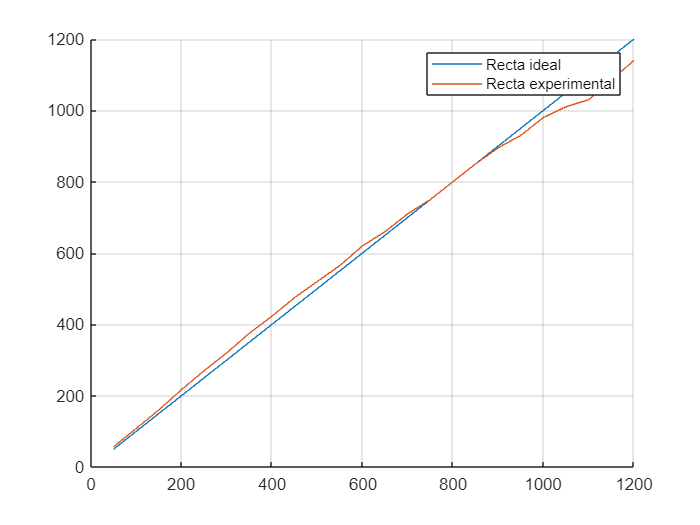

distancia_teorica=[50:50:1200];
distancia_medida = [57 108 160 217 270 320 375 423 475 520 565 620 660 710 750 800 850 895 930 980 1010 1030 1085 1140];
figure()
grid on
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida)
legend("Recta ideal","Recta experimental")
hold off

Ahora, realizamos una regresión lineal para obtener la ecuacion de ajuste de los datos experimentales.

pol = polyfit(distancia_teorica,distancia_medida,2) % ajustamos a una parábola ya que es el polinomio que mejor se ajusta a simple vitsa

pol =    -0.0001    1.1217   -1.7490


Representamos la recta de ajuste con la ideal

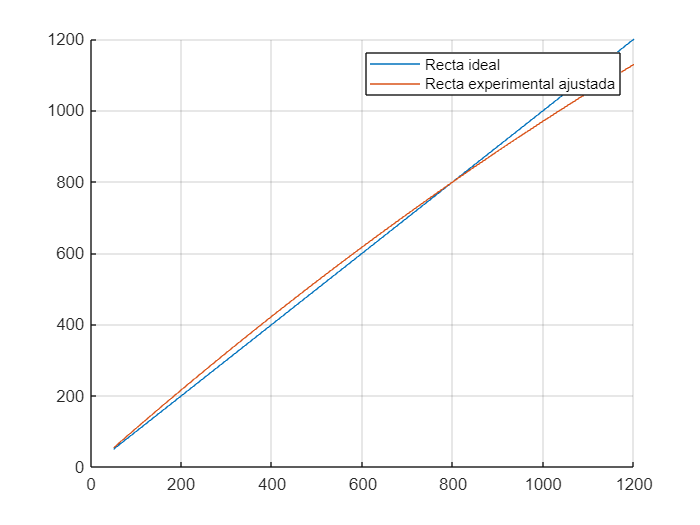

x = 50:1:1200;
y_teo = polyval([1 0],x);
y_exp = polyval(pol,x);

figure()
grid on
hold on
plot(x,y_teo)
plot(x,y_exp)
legend("Recta ideal","Recta experimental ajustada")
hold off

Si quisieramos que la recta (ajustada) experimental coincidiese con la teórica, no sería posible realizar un control proporcional con una ganancia estática, dado que el valor de dicha ganancia debe de ir cambiando en función de la entrada. Por tanto, el control del sensor lo realizaremos mediante una LookUpTable, la cual contendrá la ganancia necesaria para realizar dicho ajuste en función de la medida que arroje el sensor. Calculamos dicho vector de ganancia:

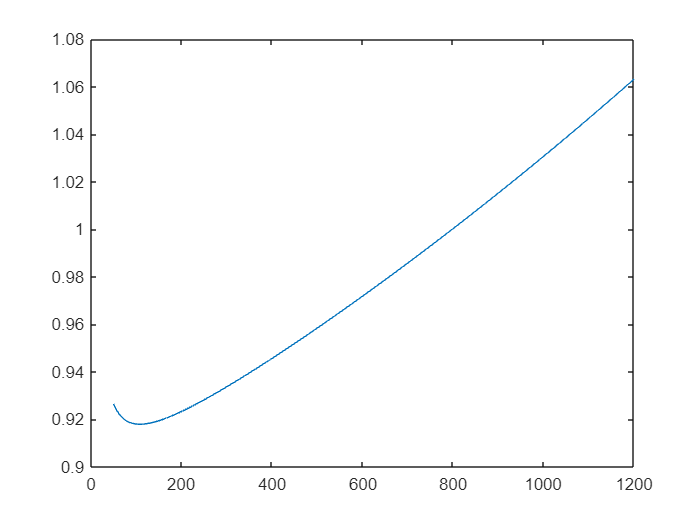

K = zeros(1,1151);

for i = 1:1:1151
    K(i) = y_teo(i)/y_exp(i);
end

figure()
plot(x,K)

Representando dicho vector de ganancias, vemos como el valor de la ganancia varía desde un valor menor a la unidad hasta un valor superior a ella, pasando por la unidad en el punto de corte entre las rectas teórica y experimental. Para comprobar la efectividad de dicho ajuste, representaremos las medias experimentales al haberles aplicado la ganancia calculada.

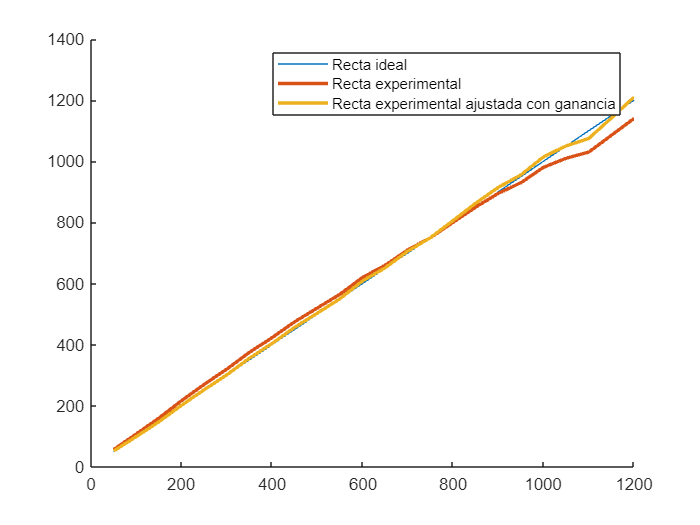

distancia_medida_ajustada = zeros(1,24);
for i = 1:1:24
    distancia_medida_ajustada(i)=distancia_medida(i)*K(distancia_medida(i));
end

figure()
hold on
plot(distancia_teorica,distancia_teorica)
plot(distancia_teorica,distancia_medida, "LineWidth",2)
plot(distancia_teorica,distancia_medida_ajustada,"LineWidth",2)
legend("Recta ideal","Recta experimental","Recta experimental ajustada con ganancia")
hold off

Comprobemos la mejora en el error después del ajuste:

error_sin_ajuste = 0;
error_con_ajuste = 0;
for i = 1:1:24
    error_sin_ajuste = error_sin_ajuste+abs(distancia_teorica(i)-distancia_medida(i))/(24*distancia_teorica(i));
    error_con_ajuste = error_con_ajuste+abs(distancia_teorica(i)-distancia_medida_ajustada(i))/(24*distancia_teorica(i));
end

mejora = (error_sin_ajuste-error_con_ajuste)*100/error_sin_ajuste

mejora = 75.8809

Es decir, el ajuste de ganancia variable supone un 75 % de mejora en la resolución del sensor.

Finalmente, lo implementaremos en Simulink mediante una LookUpTable.